# Desarrollo Laboratorio 2 - Robótica 2021-II

## Edgar Alejandro Ruíz Velasco

## Jesus Daniel Caballero Colina

## Jhohan David Contreras Aragón

**Para este equipo de trabajo se asignó el robot industrial *****Epson C4***

**Punto 1.**** Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. Haga una descripción detallada del proceso haciendo uso de imágenes y dibujos que ayuden visualizar de dónde provienen las ecuaciones encontradas.**

**(Ver punto 2)**

**Punto 2.**** En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.  **

Para el robot asignado se tiene las siguientes medidas y movimientos:

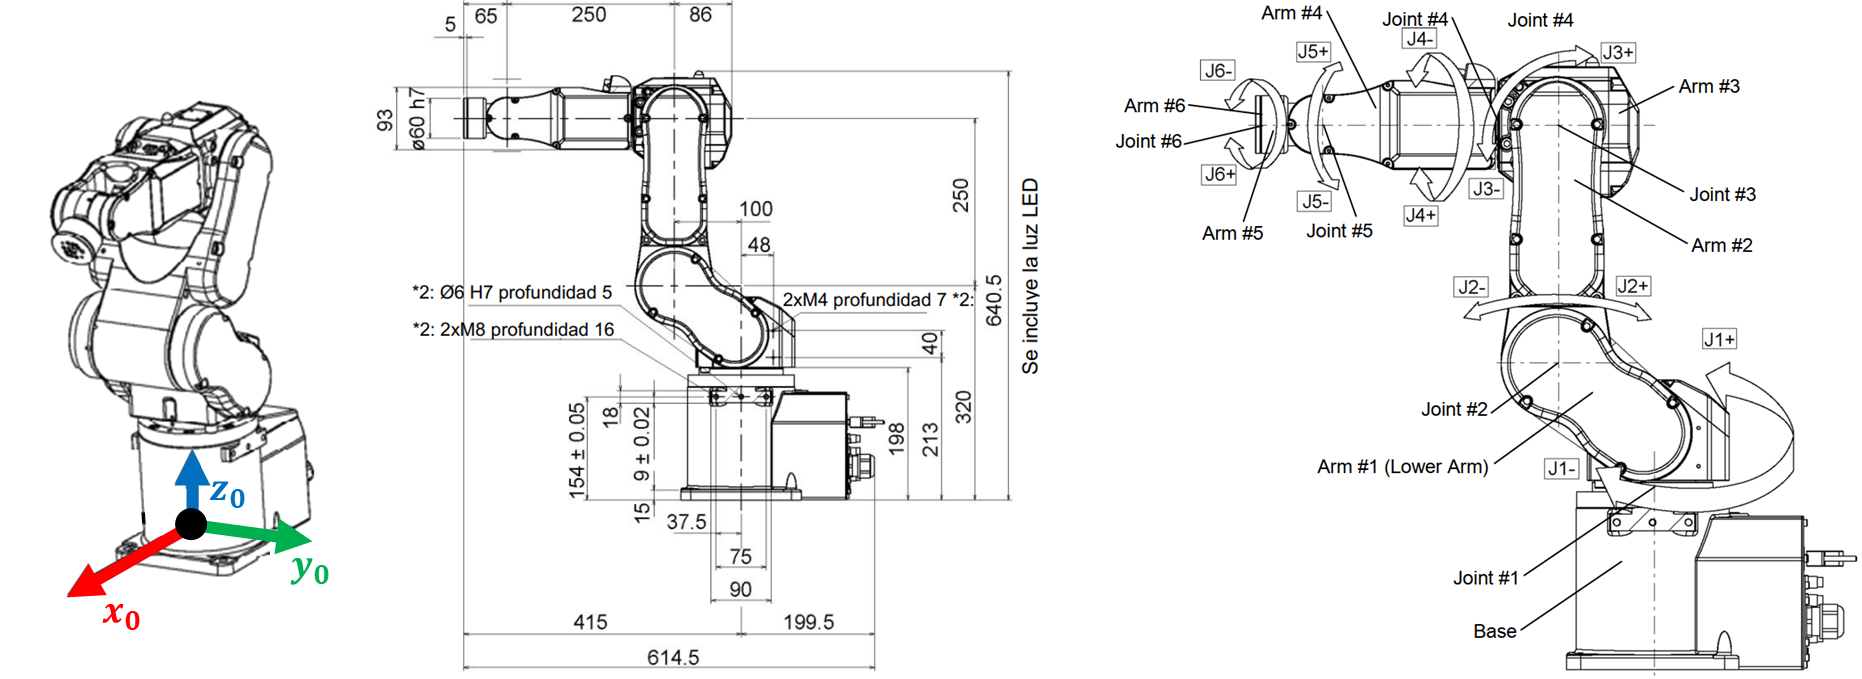

Con las gráficas anterior se realiza la ubicación de MTH y determinación de parámetros DH:

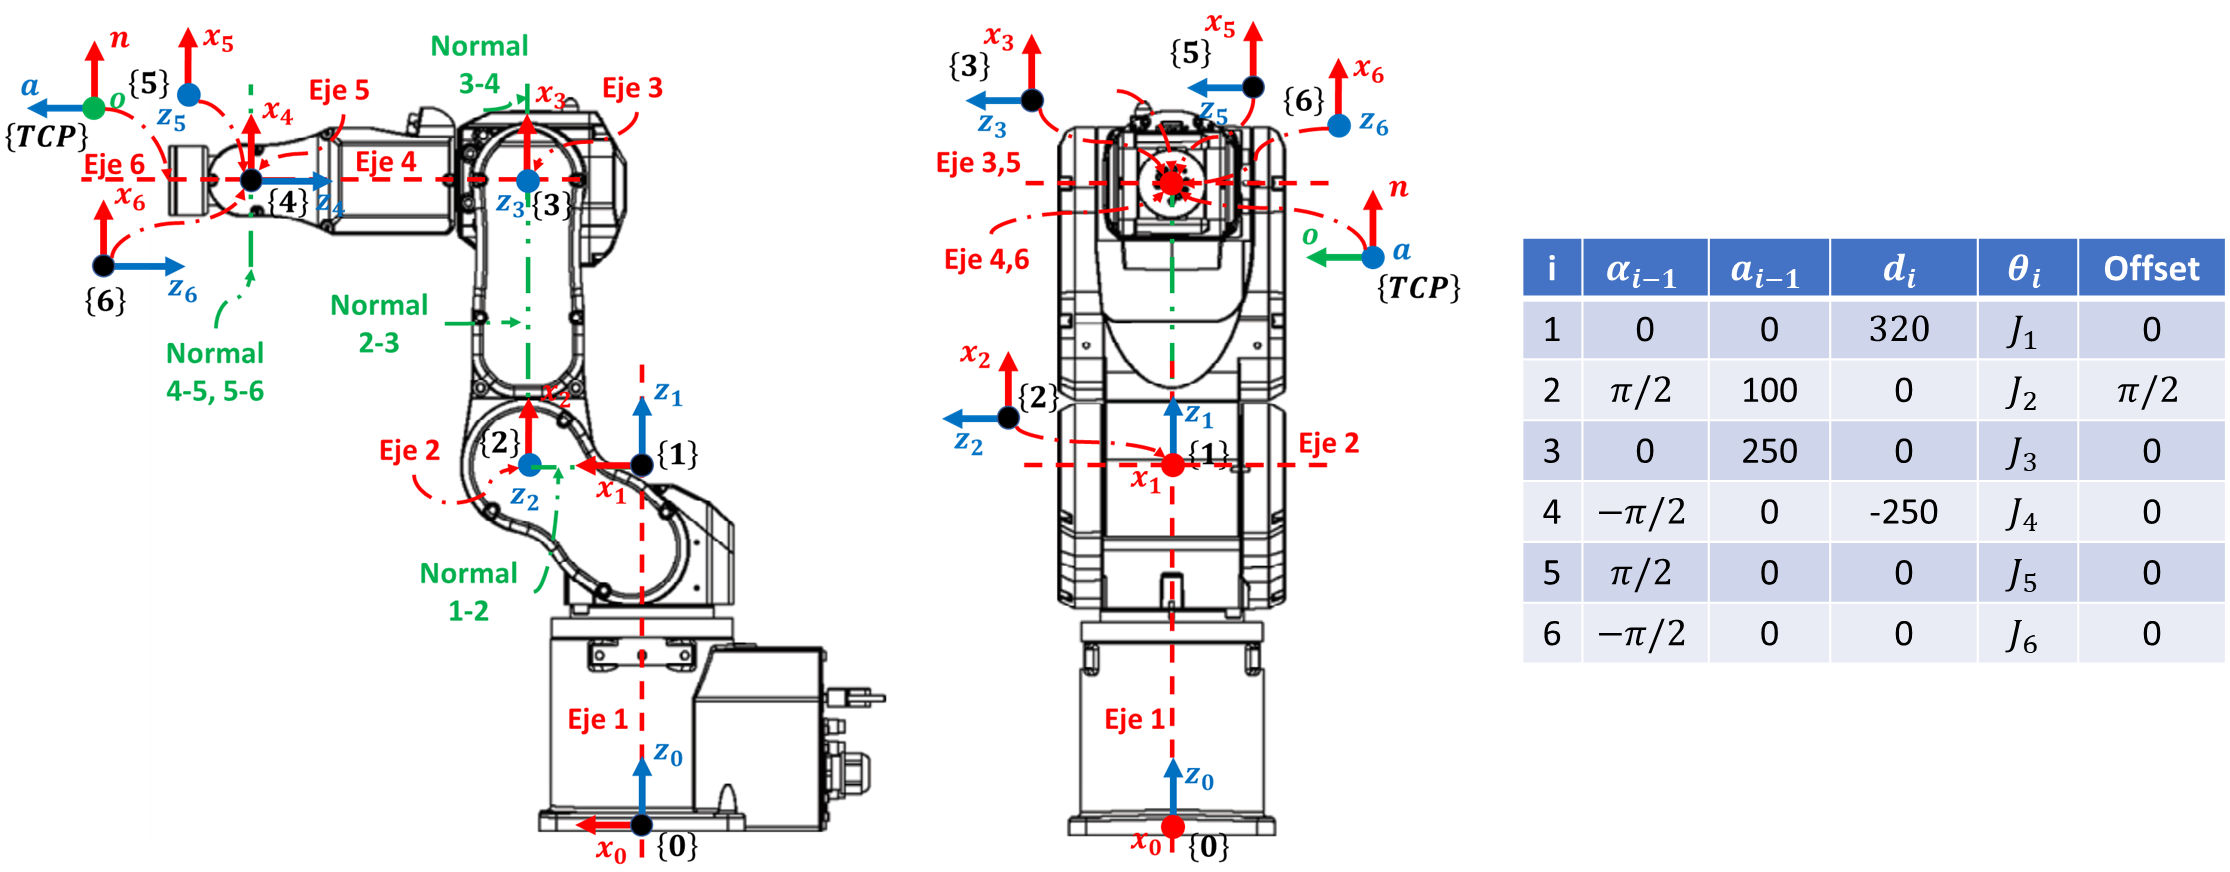

Se observa que las 3 últimas articulaciones (4, 5 y 6) se encuentran en el mismo punto. Aunque la combinación de esas 3 articulaciones no se considere como una junta esférica (y no se pueda aplicar el método Pieper completo) si se puede realizar el método de desacoplamiento cinemático hasta cierto punto. El metodo a usar es:

- Hallar la posición del punto p (posición de los sistemas de referencia 4, 5 y 6) mediante las ecuaciones de MTH

- Por método gráfico, hallar los valores de las 3 primeras articulaciones.

- Por método analítico, hallar el valor de las últimas articulaciones

**Paso 1:**

La ubicación de punto P se halla sabiendo que la pose del TCP está ya determinada. Teniendo que la ubicación de la herramienta es $X_{\textrm{TCP}} ={\left\lbrack \begin{array}{cccccc}
x & y & z & \psi  & \theta  & \phi 
\end{array}\right\rbrack }^T$ (con $\left\lbrack \begin{array}{ccc}
\theta  & \psi  & \phi 
\end{array}\right\rbrack$ ángulos rpy), se halla la matriz de rotación del sistema TCP $R_{\textrm{TCP}}$ :


$$R_{\textrm{TCP}} =\left\lbrack \begin{array}{ccc}
C\phi \ldotp C\theta  & C\phi \ldotp S\theta \ldotp S\psi -S\phi \ldotp C\psi  & C\phi \ldotp S\theta \ldotp C\psi +S\phi \ldotp S\psi \\
S\phi \ldotp C\theta  & S\phi \ldotp S\theta \ldotp S\psi -C\phi \ldotp C\psi  & S\phi \ldotp S\theta \ldotp C\psi -C\phi \ldotp S\psi \\
-S\theta  & C\theta \ldotp S\psi  & C\theta \ldotp C\psi 
\end{array}\right\rbrack$$


 Además se sabe que la posición de p cumple la ecuación:


$$X_P =X_{\textrm{TCP}} -R_{\textrm{TCP}} \left\lbrack \begin{array}{c}
0\\
0\\
65
\end{array}\right\rbrack$$



$$X_P =\left\lbrack \begin{array}{c}
x_{0,4} \\
y_{0,4} \\
z_{0,4} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x-65\ldotp \left(C\phi \ldotp S\theta \ldotp C\psi +S\phi \ldotp S\psi \right)\\
y-65\ldotp \left(S\phi \ldotp S\theta \ldotp C\psi -C\phi \ldotp S\psi \right)\\
z-65\ldotp \left(C\theta \ldotp C\psi \right)
\end{array}\right\rbrack$$


**Paso 2:**

Los esquemas simplificados que ilustran la ubicación de cada articulación con relación a sus valores son:

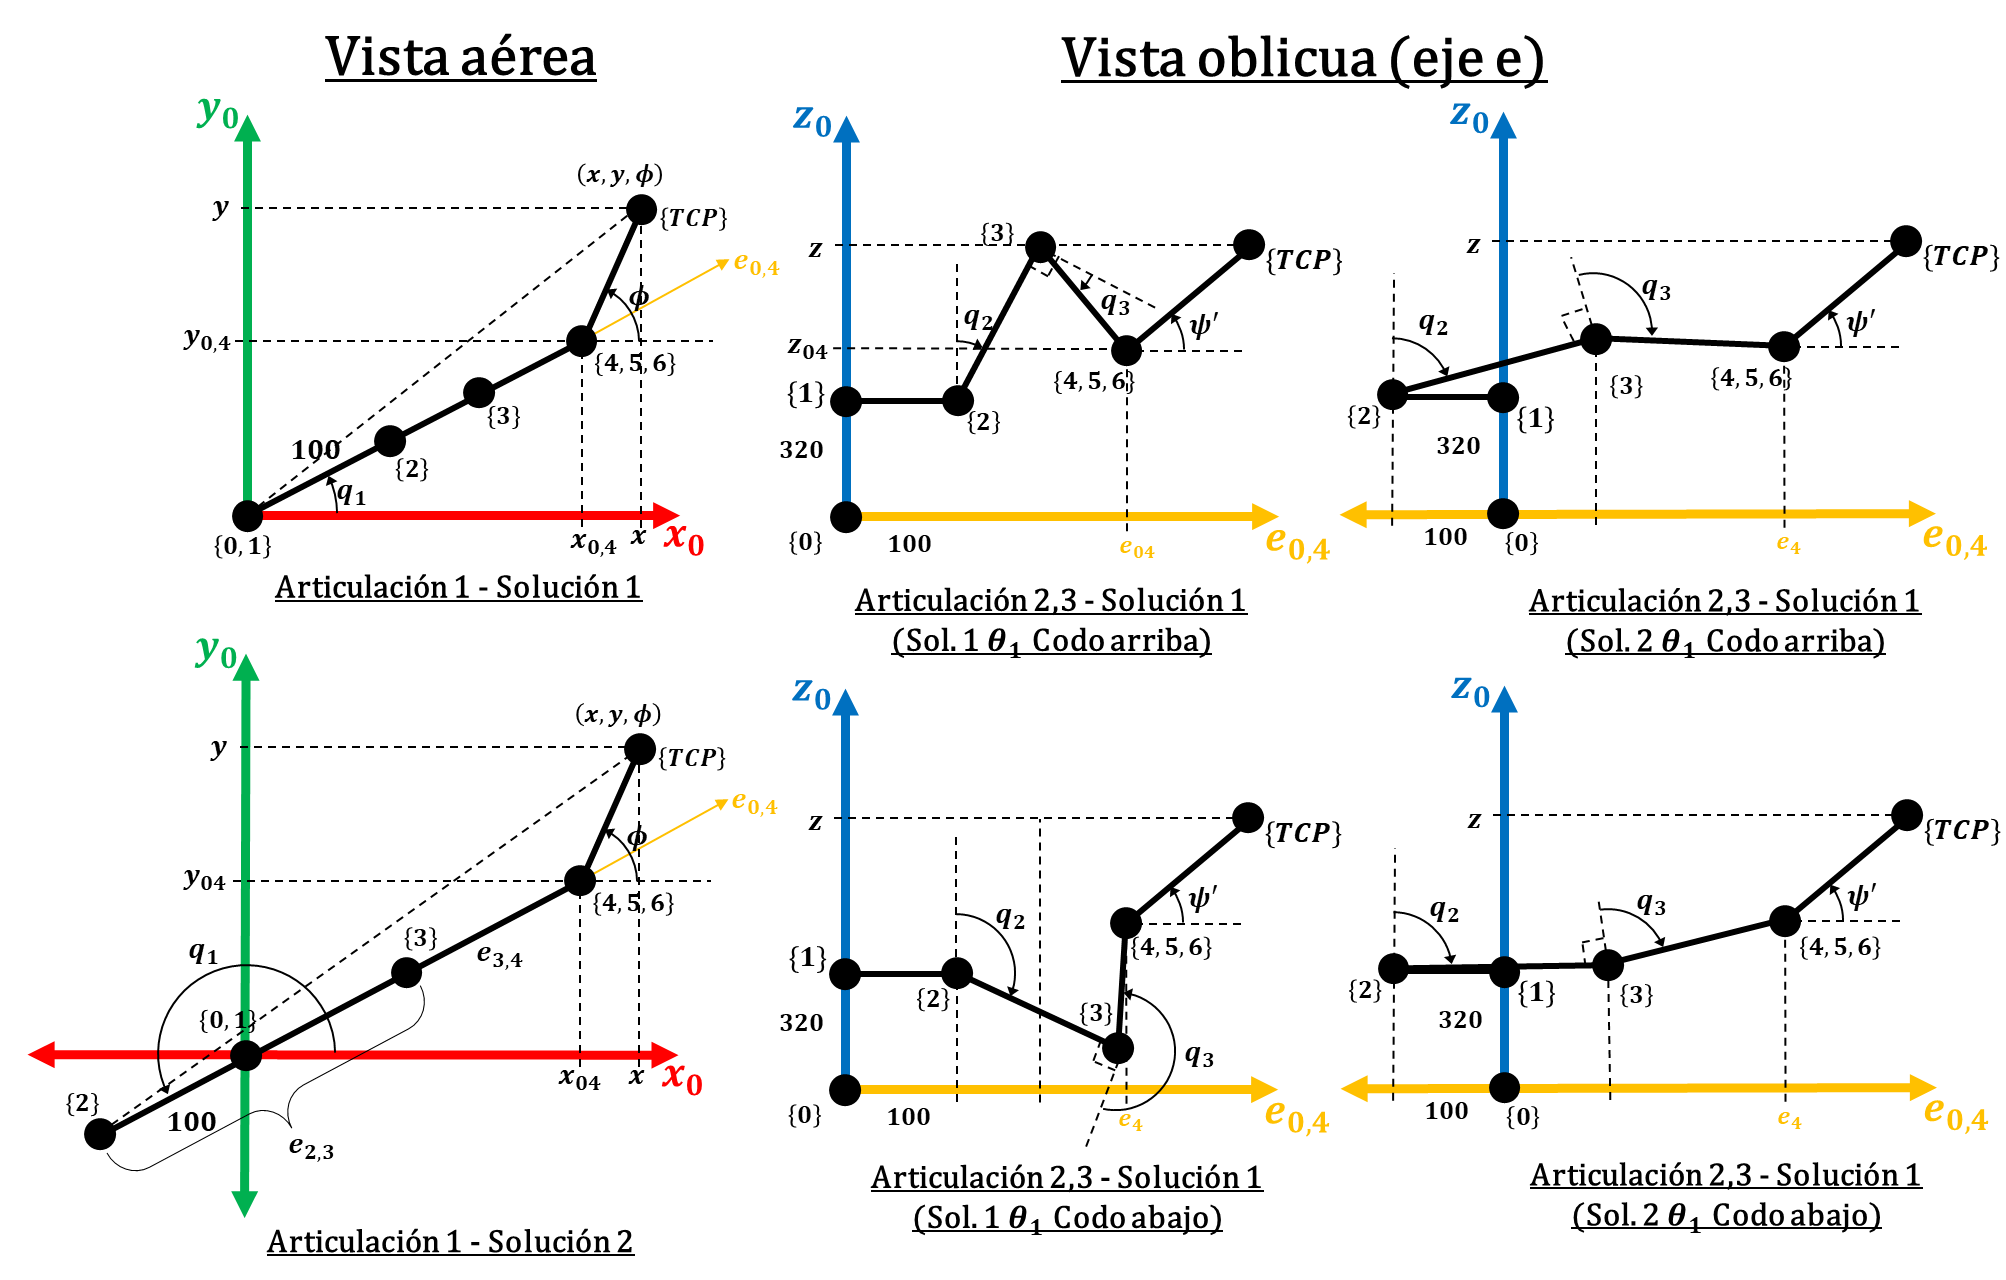

Con la vista aérea se tiene que:

$q_{1;i} =\textrm{atan2}\left(y_{0,4} ,x_{0,4} \right)$ y $q_{1;\textrm{ii}} =\textrm{atan2}\left(y_{0,4} ,x_{0,4} \right)+\pi$

Con la vista oblicua se tiene siguiente esquema:

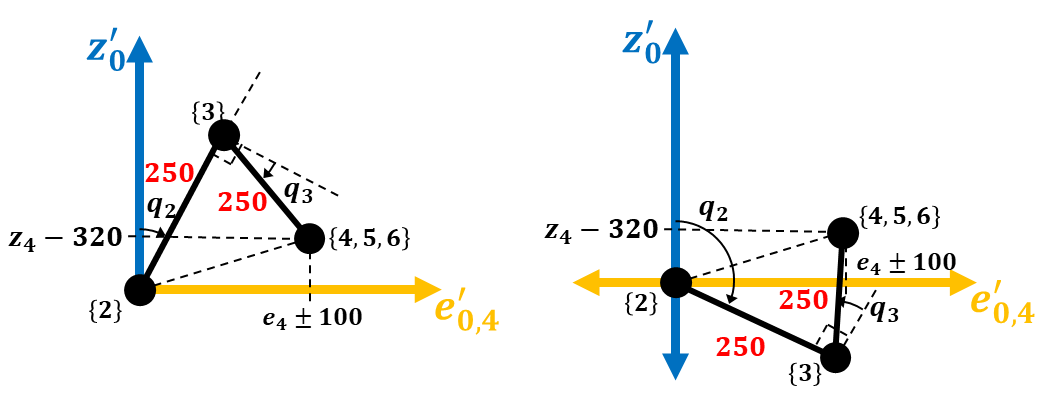

Donde:


$$e_4 =\sqrt{x_4^2 +y_4^2 }$$


Por teorema de cosenos (y teniendo en cuenta las dos soluciones de $\theta_1$):


$${\left(e_4 \pm_1 100\right)}^2 +{\left(z_4 -320\right)}^2 =2\ldotp {250}^2 -2\ldotp {250}^2 \ldotp \cos \left(180-\left(90+q_3 \right)\right)=2\ldotp {250}^2 \left(1+\cos \left(90+q_3 \right)\right)$$



$${\left(e_4 \pm_1 100\right)}^2 +{\left(z_4 -320\right)}^2 =2\ldotp {250}^2 \left(1-\sin \left(q_3 \right)\right)$$



$$\sin \left(q_3 \right)=1-\frac{{\left(e_4 -100\right)}^2 +{\left(z_4 -320\right)}^2 }{2\ldotp {250}^2 }=D_1$$



$$\sin \left(q_3 \right)=1-\frac{{\left(e_4 +100\right)}^2 +{\left(z_4 -320\right)}^2 }{2\ldotp {250}^2 }=D_2$$


Es decir que

$\cos \left(q_3 \right)=\sqrt{1-\sin^2 \left(q_3 \right)}=\pm_2 \sqrt{1-D_1^2 }$ o $\pm_2 \sqrt{1-D_2^2 }$

$q_{3;i,\textrm{ii}} =\textrm{atan2}\left(D_1 ,\pm_2 \sqrt{1-D_1^2 }\right)$o $q_{3;\textrm{iii},\textrm{iv}} =\textrm{atan2}\left(D_1 ,\pm_2 \sqrt{1-D_2^2 }\right)$

Ya teniendo $q_3$ se puede determinar $q_2$ por suma de ángulos:

$q_{2;i,\textrm{ii}} =90-\textrm{atan2}\left(z_4 -320,e_4 -100\right)-\left(45+\frac{q_{3;i,\textrm{ii}} }{2}\right)$ o $q_{2;\textrm{iii},\textrm{iv}} =90-\textrm{atan2}\left(z_4 -320,e_4 +100\right)+\left(45+\frac{q_{3;\textrm{iii},\textrm{iv}} }{2}\right)$

$q_{2;i,\textrm{ii}} =45-\textrm{atan2}\left(z_4 -320,e_4 -100\right)-\frac{q_{3;i,\textrm{ii}} }{2}$ o $q_{2;\textrm{iii},\textrm{iv}} =135-\textrm{atan2}\left(z_4 -320,e_4 +100\right)+\frac{q_{3;\textrm{iii},\textrm{iv}} }{2}$

Es decir que las soluciones quedarían:


$$\left\lbrack \begin{array}{c}
\;\textrm{Sol}\ldotp \\
q_1 \\
q_2 \\
q_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\textrm{Sol}\ldotp 1 & \textrm{Sol}\ldotp 2 & \textrm{Sol}\ldotp 3 & \textrm{Sol}\ldotp 4\\
q_{1,i}  & q_{1,i}  & q_{1,\textrm{ii}}  & q_{1,\textrm{ii}} \\
q_{2,i}  & q_{2,\textrm{ii}}  & q_{2,\textrm{iii}}  & q_{2,\textrm{iv}} \\
q_{3,i}  & q_{3,\textrm{ii}}  & q_{3,\textrm{iii}}  & q_{3,\textrm{iv}} 
\end{array}\right\rbrack$$


**Paso 3:**

Como ya se obtuvo los valores de las 3 primeras articulaciones (de una determinada solución $k$) entonces es conocido el valor de ${}^0_{\;}R^{\;}_3$:


$${}^0_{\;}R^{\;}_3={}^0_{\;}R^{\;}_1\left(q_{1,k} \right)\ldotp {}^1_{\;}R^{\;}_2\left(q_{2,k} \right)\ldotp {}^2_{\;}R^{\;}_3\left(q_{3,k} \right)=\left\lbrack \begin{array}{ccc}
C_1  & -S_1  & 0\\
S_1  & C_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
C\left(q_2 +\frac{\pi }{2}\right) & -S\left(q_2 +\frac{\pi }{2}\right) & 0\\
0 & 0 & -1\\
S\left(q_2 +\frac{\pi }{2}\right) & C\left(q_2 +\frac{\pi }{2}\right) & 0
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
C_3  & -S_3  & 0\\
S_3  & C_3  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$${}^0_{\;}R^{\;}_3=\left\lbrack \begin{array}{ccc}
C_1  & -S_1  & 0\\
S_1  & C_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
-S_2  & -C_2  & 0\\
0 & 0 & -1\\
C_2  & -S_2  & 0
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
C_3  & -S_3  & 0\\
S_3  & C_3  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$${}^0_{\;}R^{\;}_3=\left\lbrack \begin{array}{ccc}
-C_1 C_2 S_3 -C_1 S_2 C_3  & C_1 S_2 S_3 -C_1 C_2 C_3  & S_1 \\
-S_1 C_2 S_3 -S_1 S_2 C_3  & S_1 S_2 S_3 -S_1 C_2 C_3  & -C_1 \\
C_2 C_3 -S_2 S_3  & -C_2 S_3 -S_2 C_3  & 0
\end{array}\right\rbrack$$


Y por la orientación de la disposición de las 3 últimas articulaciones se sabe que la matriz de rotación desde el sistema 3 al sistema TCP (colocandolos en un mismo origen) ${}^3_{\;}R^{\;}_{\textrm{TCP}}$ tendría un valor de:


$${}^3_{\;}R^{\;}_{\textrm{TCP}}=R_{\textrm{eul},\textrm{ZYZ}} \left(-q_4 ,-q_5 ,-q_6 \right)\ldotp R_x \left(\pi \right)=\left\lbrack \begin{array}{ccc}
-S_4 S_6 +C_4 C_5 C_6  & S_4 C_6 +C_4 C_5 S_6  & -C_4 S_5 \\
-C_4 S_6 -S_4 C_5 C_6  & C_4 C_6 -S_4 C_5 S_6  & S_4 S_5 \\
S_5 C_6  & S_5 S_6  & C_5 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & -1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack$$



$${}^3_{\;}R^{\;}_{\textrm{TCP}}=\left\lbrack \begin{array}{ccc}
-S_4 S_6 +C_4 C_5 C_6  & -S_4 C_6 -C_4 C_5 S_6  & C_4 S_5 \\
C_4 S_6 +S_4 C_5 C_6  & C_4 C_6 -S_4 C_5 S_6  & S_4 S_5 \\
-S_5 C_6  & S_5 S_6  & C_5 
\end{array}\right\rbrack$$


Es decir que ${}^3_{\;}R^{\;}_{\textrm{TCP}}$ deseado en termino de $X_{\textrm{TCP}}$ y las 3 primeras articulaciones es:


$${}^3_{\;}R^*_{\textrm{TCP}}={}^0_{\;}R^{\;T}_3\ldotp {}^0_{\;}R^{\;}_{\textrm{TCP}}={\left\lbrack \begin{array}{ccc}
-C_1 C_2 S_3 -C_1 S_2 C_3  & C_1 S_2 S_3 -C_1 C_2 C_3  & S_1 \\
-S_1 C_2 S_3 -S_1 S_2 C_3  & S_1 S_2 S_3 -S_1 C_2 C_3  & -C_1 \\
C_2 C_3 -S_2 S_3  & -C_2 S_3 -S_2 C_3  & 0
\end{array}\right\rbrack }^T \ldotp \left\lbrack \begin{array}{ccc}
C\phi \ldotp C\theta  & C\phi \ldotp S\theta \ldotp S\psi -S\phi \ldotp C\psi  & C\phi \ldotp S\theta \ldotp C\psi +S\phi \ldotp S\psi \\
S\phi \ldotp C\theta  & S\phi \ldotp S\theta \ldotp S\psi -C\phi \ldotp C\psi  & S\phi \ldotp S\theta \ldotp C\psi -C\phi \ldotp S\psi \\
-S\theta  & C\theta \ldotp S\psi  & C\theta \ldotp C\psi 
\end{array}\right\rbrack$$



$${}^3_{\;}R^*_{\textrm{TCP}}=\left\lbrack \begin{array}{ccc}
a_{11}  & a_{12}  & a_{13} \\
a_{21}  & a_{22}  & a_{23} \\
a_{31}  & a_{32}  & a_{33} 
\end{array}\right\rbrack$$


E igualando ${}^3_{\;}R^*_{\textrm{TCP}}$ y ${}^3_{\;}R^{\;}_{\textrm{TCP}}$, se puede obtener las siguientes igualdades:


$$q_4 =\textrm{atan2}\left(a_{23} ,a_{13} \right)$$



$$q_5 =\textrm{atan2}\left(a_{31}^2 +a_{32}^2 ,a_{33} \right)$$



$$q_6 =\textrm{atan2}\left(a_{32} ,-a_{31} \right)$$


Estas ecuaciones se implementaron en el archivo EpsonC4_IC.m

**Punto 3.**** Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el *****Toolbox *****explique:**

**¿Cuál es la diferencia entre estas funciones?**

En la libreria RVC se encuentran concretamente siete funciones que pueden ser usaadas para calculos de cinematica inversa. La funcion** ikcon** indica una de las configuraciones posibles de valores de las articulaciones que permite obtener la pose deseada, esto mediante una solucion numerica con limites en las articulaciones. Las funciones **ikine** y** ikunc **tambien utilizan soluciones numericas pero sin restricciones en las articulaciones. La funcion **ikine3** permite obtener a partir de una entrada que especifique las pose de el efector final una solucion analitica para robots de tres ejes sin muñeca como puede ser el caso de robots desacoplados cinematicamente. La funcion **ikine6s** mediante solucion analitica calcula a partir de una pose una configuracion de posiciones de las articulaciones para robots de seis ejes con muñeca esferica. La funcion **ikine_sym** permite calcular mediante variables simbolicas las diferentes posibles configuraciones siendo la herramienta mas general para la obtencion de soluciones analiticas algebraicas. Finalmente la funcion **ikinem** permite obtener una solucion numerica a partir de una pose utilizando el minimizador Levenberg-Marquad.

**¿Cuál debe usar para su robot y por que? (Revise la documentación del *****Toolbox*****)**

Para éste caso se opta por el uso de funciones que calculen analiticamente debido a que las soluciones numericas son genralmente mas lentas que las cerradas, usaremos **ikine_sym** para calcular una solucion mediante variables simbolicas y posteriormente se pensó en usar la funcion **ikine6s** para casos puntuales dado que en su construccion esta pensada para nuestro caso especifico, es decir un robot de seis ejes con muñeca de articulacion esferica, sin embargo solo funciona para modelos construidos mediante la convención Denavit-Hartenberg estandar, por este motivo se opto por el uso de una solucion numerica, concretamente **ikcon **la cual permite tener en cuenta los limites de las articulaciones.

Para el uso de la funcion **ikine_sym **se desglosa el robot en dos partes con tres grados de libertad cada una determinando orientacion y posicion del efector final de forma independiente y así obtener para las primeras tres articulaciones las dos soluciones analiticas de cada articulacion para la determinacion de una posicion arbitraria y luego para las ultimas tres que conforman una articulacion esferica sus respectivas soluciones para la determinacion de la orientacion del efector final.

T6b = trotx(pi)*transl([0 0 6.5]);
T6b=[1 0 0 0; 0 -1 0 0; 0 0 -1 -6.5; 0 0 0 1];

%     MDHm(thetai,      di,    ai-1,  alpha-1,   sigma, offset)
Links(1) = Link('revolute','alpha',0,    'a',0, 'd',32, 'offset',0,'modified', 'qlim',[-17*pi/18 17*pi/18]);
Links(2) = Link('revolute','alpha',pi/2, 'a',10,'d',0,  'offset',pi/2,'modified', 'qlim',[-8*pi/9 13*pi/36]);
Links(3) = Link('revolute','alpha',0,    'a',25,'d',0,  'offset',0,   'modified', 'qlim',[-17*pi/60 5*pi/4]);
Links(4) = Link('revolute','alpha',-pi/2,'a',0, 'd',-25,'offset',0,   'modified', 'qlim',[-10*pi/9 10*pi/9]);
Links(5) = Link('revolute','alpha',pi/2, 'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-3*pi/4 3*pi/4]);
Links(6) = Link('revolute','alpha',-pi/2,'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-2*pi 2*pi]);

Epson_C4 = SerialLink(Links,'name','Epson C4','tool',T6b)

 
Epson_C4 = 
 
Epson C4 (6 axis, RRRRRR, modDH, fastRNE)                                     
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|         32|          0|          0|          0|             
|  2|         q2|          0|         10|      1.571|      1.571|             
|  3|         q3|          0|         25|          0|          0|             
|  4|         q4|        -25|          0|     -1.571|          0|             
|  5|         q5|          0|          0|      1.571|          0|             
|  6|         q6|          0|          0|     -1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                    

for i=1:3 
    L_P(i)=Links(i);
    L_O(i)=Links(i+3);
end

TV1=trotx(-pi/2)*transl([0 0 -25]);

Epson_C4_T = SerialLink(L_P,'name','Epson C4 T','tool',TV1)

 
Epson_C4_T = 
 
Epson C4 T (3 axis, RRR, modDH, fastRNE)                                         
                                                                                 
+---+-----------+-----------+-----------+-----------+-----------+                
| j |     theta |         d |         a |     alpha |    offset |                
+---+-----------+-----------+-----------+-----------+-----------+                
|  1|         q1|         32|          0|          0|          0|                
|  2|         q2|          0|         10|      1.571|      1.571|                
|  3|         q3|          0|         25|          0|          0|                
+---+-----------+-----------+-----------+-----------+-----------+                
                                                                                 
grav =    0  base = 1  0  0  0   tool =  1            0            0            0
          0         0  1  0  0           0            0            1          -2

Epson_C4_O = SerialLink(L_O,'name','Epson C4 O','tool',T6b)

 
Epson_C4_O = 
 
Epson C4 O (3 axis, RRR, modDH, fastRNE)                                      
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|        -25|          0|     -1.571|          0|             
|  2|         q2|          0|          0|      1.571|          0|             
|  3|         q3|          0|          0|     -1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                                                              
grav =    0  base = 1  0  0  0   tool =  1           0           0           0
          0         0  1  0  0           0          -1           0           0
       9.81         0  0  1  0    

A partir de aca el procedimiento se describe mediante imagenes, ésto debido a que la funcion **ikine_sym **usa la funcion findsym de la libreria Symbolic Math Toolbox la cual no está disponible en las versiones actuales de MAtlab por lo que el procedimiento debio ser llevado a cabo en la version 2017b de software y se muestra a continuacion.

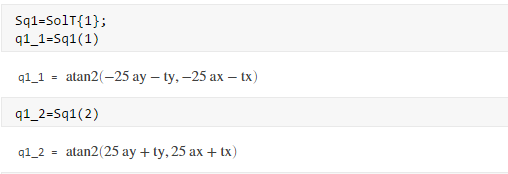

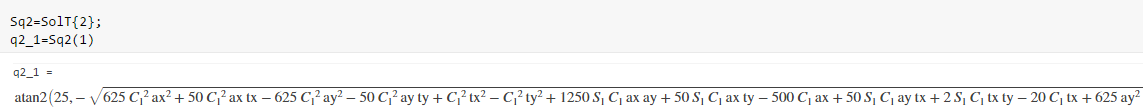

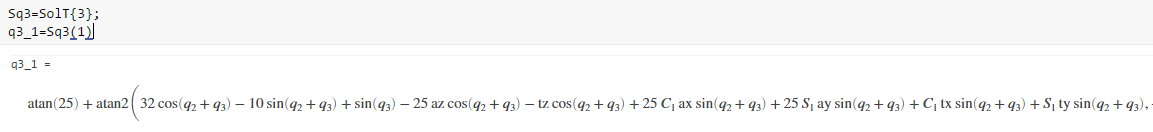

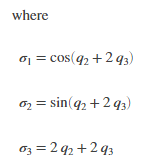

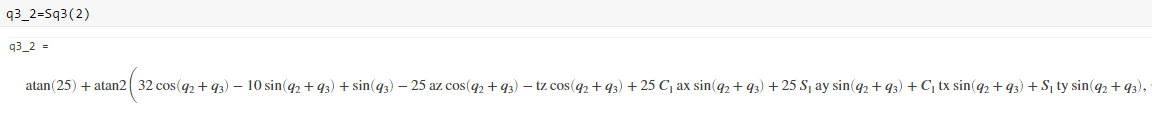

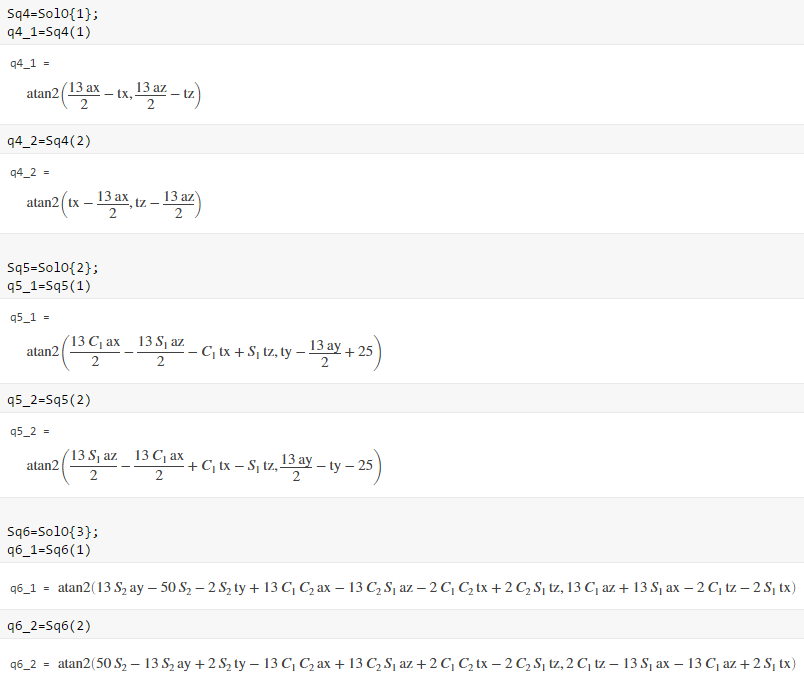

Para el uso de** ikcon **se debe establecer una pose especifica arbitraria la cual se obtiene aleatoriamente de la siguiente manera.

dhparams = [0,   0,	   0.32, 0;
            0.10,pi/2, 0     0;
            0.25,0,	   0,  	 0;
            0,   -pi/2,-0.25,0;
            0,   pi/2, 0,    0;
            0,   -pi/2,0 ,   0;
            0,   pi,   0.065,0];
robot = rigidBodyTree;

body1 = rigidBody('body1');
body2 = rigidBody('body2');
body3 = rigidBody('body3');
body4 = rigidBody('body4');
body5 = rigidBody('body5');
body6 = rigidBody('body6');
body7 = rigidBody('TCP');

jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = pi/2;
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = pi/2;
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0;
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0;
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0;
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0;
jnt7 = rigidBodyJoint('jntTCP','revolute');
jnt7.HomePosition = 0;

setFixedTransform(jnt1,dhparams(1,:),'mdh');
setFixedTransform(jnt2,dhparams(2,:),'mdh');
setFixedTransform(jnt3,dhparams(3,:),'mdh');
setFixedTransform(jnt4,dhparams(4,:),'mdh');
setFixedTransform(jnt5,dhparams(5,:),'mdh');
setFixedTransform(jnt6,dhparams(6,:),'mdh');
setFixedTransform(jnt7,dhparams(7,:),'mdh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;
body7.Joint = jnt7;

addBody(robot,body1,'base')
addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')
%addBody(robot,body7,'body6')
config_home = homeConfiguration(robot);
config = homeConfiguration(robot);

aik = analyticalInverseKinematics(robot);
opts = showdetails(aik);

--------------------
Robot: (6 bodies)

Index      Base Name   EE Body Name     Type                    Actions
-----      ---------   ------------     ----                    -------
    1           base          body6   RRRSSS   Use this kinematic group



aik.KinematicGroup = opts(1).KinematicGroup;
disp(aik.KinematicGroup)

               BaseName: 'base'
    EndEffectorBodyName: 'body6'



generateIKFunction(aik,'willowRobotIK');
rng(0);
expConfig = randomConfiguration(robot)

expConfig = 1×6 struct array with fields:
    JointName
    JointPosition


eeBodyName = aik.KinematicGroup.EndEffectorBodyName;
baseName = aik.KinematicGroup.BaseName;
expEEPose = getTransform(robot,expConfig,eeBodyName,baseName)

expEEPose =    -0.5367   -0.8283    0.1612    0.0223
    0.7234   -0.3533    0.5932   -0.0517
   -0.4344    0.4349    0.7887    0.2148
         0         0         0    1.0000



qq=Epson_C4.ikcon(expEEPose)

qq =    -1.8232   -2.5757    0.1192    3.1337    1.5939    2.3660


**Punto 4.**** Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.**

Aprovechando la creacion del modelo del robot en RST realizada en el codigo anterior y usando la funcion **analyticalInverseKinematics **que permite el calculo de una de las soluciones de cinematica inversa de forma analitica.

ikConfig = willowRobotIK(expEEPose,false);
eeWorldPose = getTransform(robot,expConfig,eeBodyName);

generatedConfig = repmat(expConfig, size(ikConfig,1), 1)

generatedConfig = 8×6 struct array with fields:
    JointName
    JointPosition


SS1=generatedConfig(1,:)

SS1 = 1×6 struct array with fields:
    JointName
    JointPosition


**Punto 5.**** Compare los métodos.**

Para el caso se compara la fincion **ikcon **del Robotics Vision Control con la funcion **analyticalInverseKinematics **del Robotics Sistem Toolbox, la principal diferencia entre éstos el metodo utilizado para realizar el calculo de las soluciones, por un lado el primero utiliza un metodo numerico iterativo que permite la obtencion de solo un conjunto de soluciones, por otro lado el segundo obtiene la solucion de forma analitica calculando todas las soluciones de forma cerrada. Ambas funciones son compatibles con modelos de robot de seis grados de libertad.

**Punto 6.**** Compruebe mediante su modelo geométrico inverso la configuración del robot para las posturas de la herramienta halladas en el anterior laboratorio, tales como puntos de calibración.**

El punto de calibración se encuentra en:

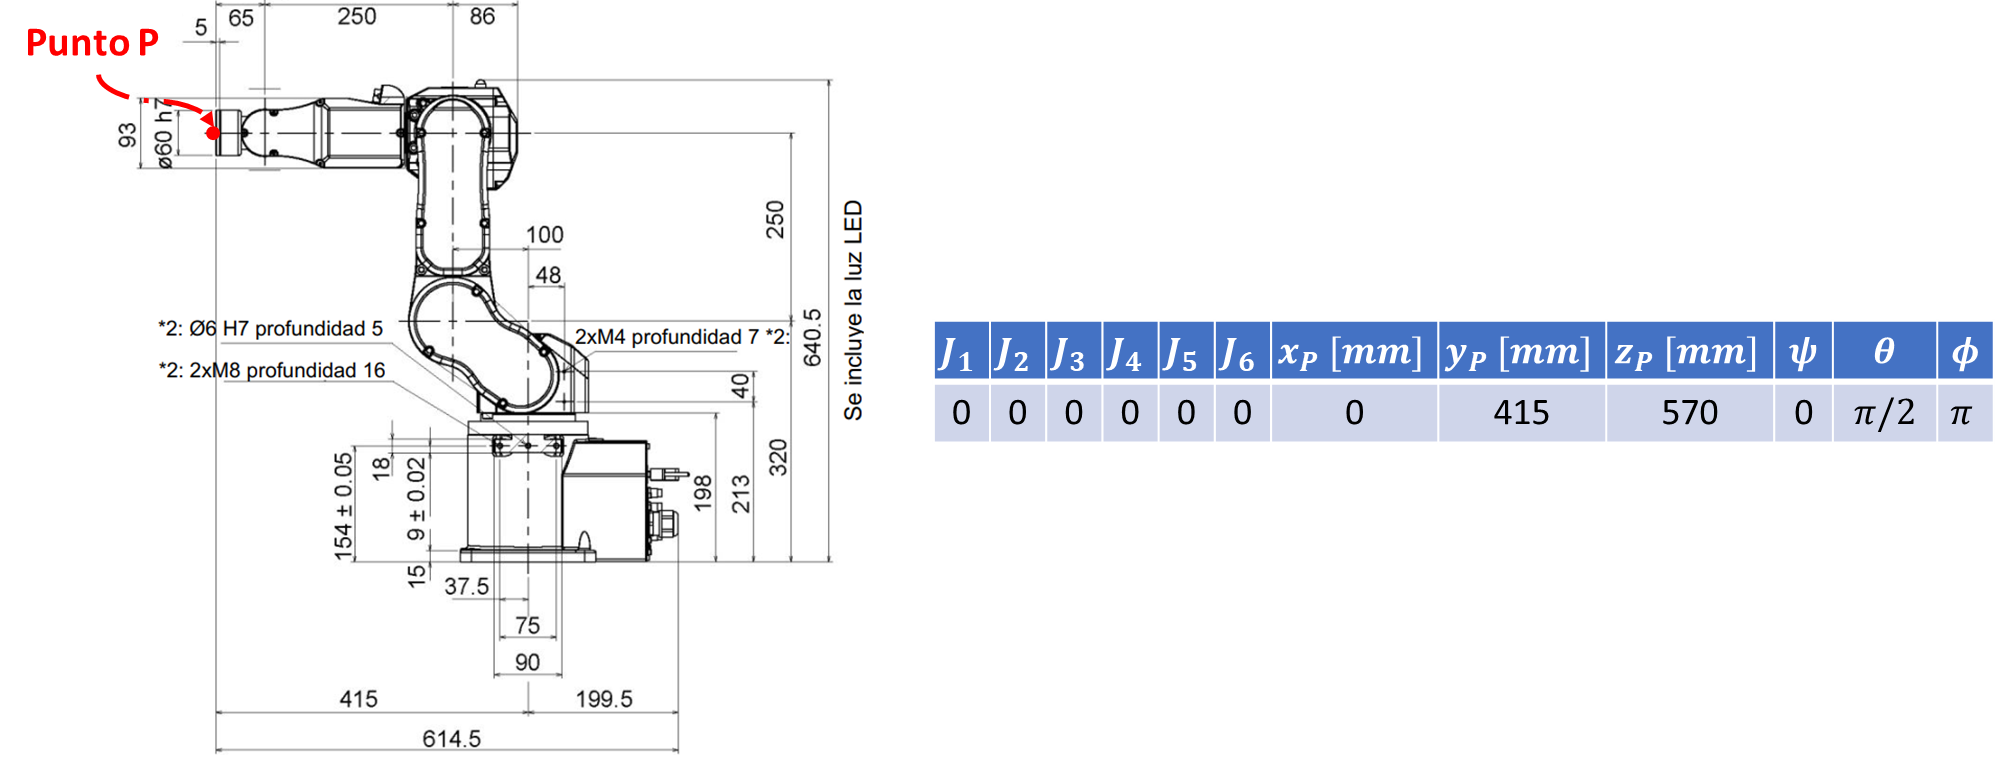

Configs = EpsonC4_IC([415 0 570 0 pi/2 pi])

Configs =          0         0         0         0         0   -0.0000
         0  -90.0000  180.0000         0  -90.0000    0.0000
         0         0         0         0         0         0
         0         0         0         0         0         0


**Punto 7.**** Proponga 4 posturas (*****x, y, z, roll, pitch, yaw*****)'** **que estén dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla 1:**

**Punto 8.**** Haciendo uso de la GUI verifique que con la configuración calculada se obtiene la postura indicada de la herramienta. Haga capturas de pantalla resaltando con cotas los valores *****x y z*****, e incluya en el informe los resultados**

**Punto 9.**** Actualice la GUI para que tenga la opción de ingresar la posición de la herramienta, obtener la configuración del robot mediante cinemática inversa y observar el robot en la posición. Compruebe su funcionamiento.**